# One-Sample T-Tests

*Bart Krekelberg - Last Update Jan 2023.*

The (one-sample) T-Test is probably the most commonly used statistical test. You use it when you've m*easured one quantity several times and want to know whether the average is different from some specified value.*

## An Example Experiment

Your subjects are doing a task in which they are told to attend to a pattern that will appear on the right side of the screen while looking straight ahead. You suspect that the subjects may not be looking straight ahead. To test this, you measure the eye position (in all that follows we will consider this to be the real experimental data!):

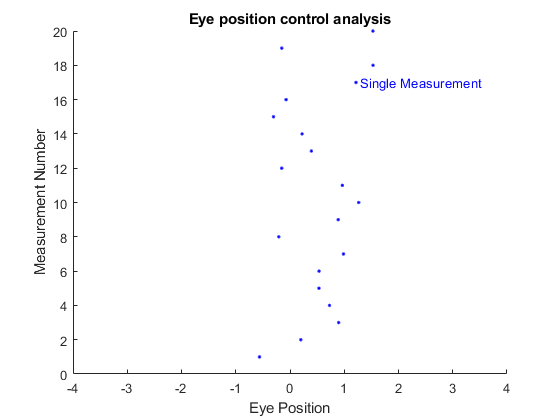

clear variables; % Start with a clean slate
rng(1230,'twister'); % Keep random numbers repeatable between runs
% Generate fake measurements
nrMeasurements   = 20;
eyePosition = 0.5 + randn(nrMeasurements,1);
minX = -4;
maxX =  4;
dX = 0.01;
% Show the raw measurements
figure(1);
clf;
axDots =gca;
hold on
plot(eyePosition,1:nrMeasurements,'.b');
text(eyePosition(17),17,' Single Measurement','color','b');
xlabel('Eye Position')
ylabel('Measurement Number')
set(gca,'XTick',minX:1:maxX,'XLim',[minX maxX]);
title('Eye position control analysis');

Just looking at these raw data, it seems that indeed this subject tends to look to the right even when instructed to look straight ahead. How do we go from "it seems" to a statistical statement?

We know that the measurement of eye position is noisy: even if the eye stays in exactly the same spot, we will not measure the exact same eye position every time. This is the nature of experimental measurement; it is noisy. Based on this it should be clear that what we want to demonstrate is not that any individual measurement of eye position was bigger than zero , but that the measurements were bigger than zero **on average**. Let's add the mean to the plot:

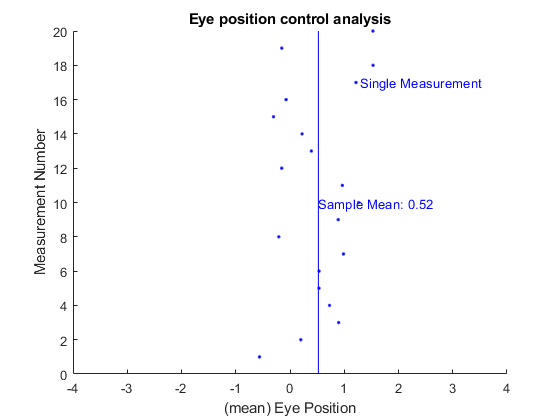

meanEyePosition = mean(eyePosition);
plot([meanEyePosition meanEyePosition],get(gca,'YLim'),'b');
text(meanEyePosition,nrMeasurements/2,['Sample Mean: ' num2str(meanEyePosition,2)],...
    'Color','b');
xlabel '(mean) Eye Position'

## Statistical Analysis by Monte Carlo Simulation

The mean is bigger than zero, but how do we know that this did not happen by chance, just because the measurement was noisy? To quantify this, we can **simulate** taking noisy measurements of a subject looking perfectly straight ahead. We'll repeat this process many times (`nrRepeats`). This simulates a perfect observer (looking perfectly straight ahead) whose eye position is recorded with an imperfect measurement process. Such a simulation of noisy experimental data, partially based on the real data, is called a Monte Carlo simulation, after the many casinos in Monte Carlo.

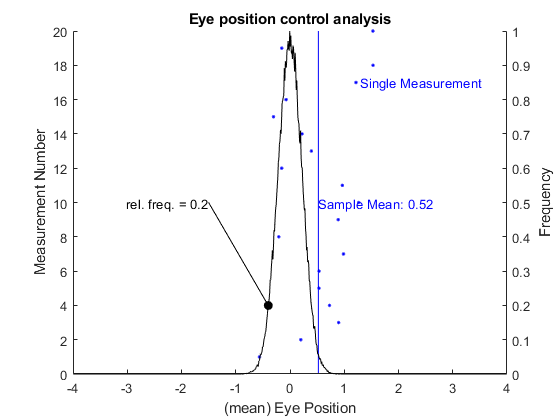

nrRepeats =100000;
straightAhead = 0 + randn(nrMeasurements,nrRepeats);
% Now calculate the means of these simulated experiments
meanStraightAhead = mean(straightAhead);
% Determine the relative frequency (histogram)
eyePosEdges = minX:dX:maxX;
eyePosBins  = eyePosEdges(1:end-1)+dX/2; % The middle of the bin
[count] = histcounts(meanStraightAhead,eyePosEdges,'Normalization','count');
relativeFrequency = count/max(count);
% Create a new panel on top of the existing one, with the same size, but
% the y-axis on the right side.
ax = axes('position',get(gca,'position'),'YAxisLocation','right','XTick',[],...
    'XLim',[minX maxX],'Color','None','YLim',[0 1]);
hold on
plot(eyePosBins,relativeFrequency,'k');
ylabel 'Frequency'
% Show the value of the relative frequency closest to testPos 
testPos = -0.4;
[~,testIx] = min(abs(testPos-eyePosBins));
stopY = relativeFrequency(testIx);
startX = -1.5;
startY = 0.5;
line([startX testPos],[startY stopY],'Color','k')
plot(testPos,stopY,'ok','MarkerFaceColor','k')
text(startX,startY,['rel. freq. = ' num2str(stopY,2)],'HorizontalAlignment','right')

The black function shows the relative frequency with which `nrMeasurements` measurements of the eye position in which the subject was really looking straight ahead will have a given mean. As expected, a mean of zero is most frequent (i.e. the curve peaks at zero). But an eye position of -0.4 (`testPos`) is not uncommon. It occurs about 20% as often as a mean of zero. 

Comparing the blue line (the mean of our experimental data) to the black curve shows that the mean eye position we observed in the experimental data (`meanEyePosition` : 0.52) is relatively uncommon if the subject were actually looking straight ahead. 

To convert this into a statement of significance we have to take one additional step. We calculate what is called the cumulative frequency; the frequency with which the outcome (the mean) is less than or equal to a certain value. We determine it by first calculating the cumulative sum and then divide by the number of repeats. 

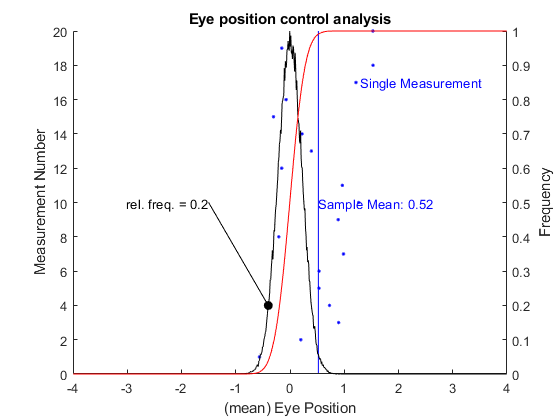

cumulative = cumsum(count)/nrRepeats;
plot(eyePosBins,cumulative,'r');

There are a few interesting points on this red curve. 

- The curve is zero for all mean eye positions less than -1. This means that such negative means never occurred in all of the `nrRepeats` we simulated.

- The curve crosses 0.5 at a mean eye position of zero. This means that in the simulated straight ahead data half of all means had a value less than or equal to zero. 

- At high values of the mean eye position, the curve saturates at 1. This means that mean values higher than the saturation point never occured. (Or, equivalently, that all mean values that did occur, were smaller).

- The most interesting point is the value of the cumuluative frequency at the mean eye position of the data (i.e. the intersection of the red curve and the blue line) Let's calculate its value: 

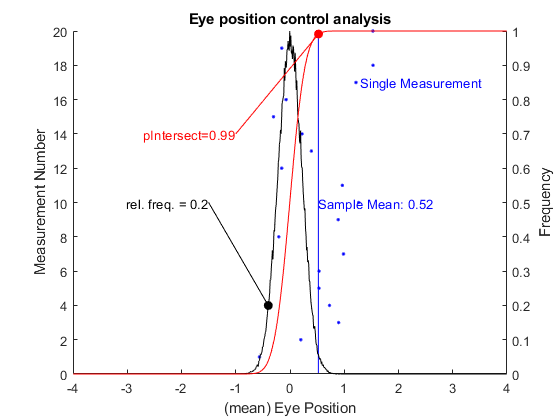

ix  = find(eyePosBins>meanEyePosition,1,'first'); %First value beyond meanEyePosition
pIntersect = cumulative(ix);
xStart = -1;
yStart = 0.7;
xStop = eyePosBins(ix);
line([xStart xStop],[yStart pIntersect],'Color','red')
plot(xStop,pIntersect,'ro','MarkerFaceColor','red');
text(xStart,yStart,['pIntersect=' num2str(pIntersect,2)],'HorizontalAlignment','right',...
    'color','r')

pValueMonteCarlo = 1-pIntersect;

This number (`pIntersect` : 0.99) is the fraction of means in the simulated straight ahead data that was less than or equal to the observed value in the real experiment.

From this we derive a statement of statistical significance. 99% of straight ahead recordings would result in a mean smaller than the one we observed. This implies that a value as large as our measurement or larger would only occur in 1% of all trials if the subject were actually looking ahead. In other words, it is unlikely (1% of simulated cases) that our subject was really looking ahead and that we only observed the mean eye position we did observe (`meanEyePosition`) due to measurement noise. 

**We conclude that the subjects mean eye position was significantly(p<0.01) deviated to the right of zero.**

## Using more formal language

The description above uses informal language to describe the statistical analysis. Let's translate some of the concepts/procedures into more formal language.

- **"You suspect that the subjects may not be looking straight ahead":** You are trying to disprove the hypotheses that the subject is looking straight ahead. This is called the *null hypothesis* and sometimes referred to as H0. (The alternative hypothesis, that the subject is looking to the right is then referred to as H1). Note that in the traditional frequentist hypothesis testing framework you cannot prove that H1 is correct, you can only show that H0 is unlikely to be correct. 

- **"Measurements are noisy":** Measurements are *random variables*, drawn from a *probability distribution*. In the examples above we assumed that the probablity distribution was a normal distribution with a mean of 0 and a standard deviation of 1. The `randn` function in Matlab returns numbers from this probablity distribution.

- **"What we want to demonstrate is not that any individual measurement of eye position was bigger than zero , but that the measurements were bigger than zero on average":** From our measurements we extract a *test statistic*. We used the mean as a statistic, but in general, any function of the measurments can serve as a statistic. You can think of it as a summary of your data.

- **"The measurements":** The collection of measurements is called the *sample* in statistics. This can be confusing as we often use the word sample to refer to a single measurement. The word 'sample' in One -Sample Tests refers to the statistical kind of sample: we have measured one quantity multiple times and want to draw some conclusion about that sample of measurements.

- **"We can simulate taking noisy measurements of a subject looking straight ahead":** We estimate the probability distribution of the test statistic under the null hypothesis. Put differently, we assume the null hypothesis is true, generate surrogate data sets (surrogate *samples*) that fit with the null hypothesis, calculate the test statistic for each of the surrogte sets (*samples*), and determine the resulting distribution (i.e. histgoram) of the test statistic. This is also called the *null distribution*: the distribution of values of the test statistic that would be expected if the null hypothesis were true.

- **"The relative frequency with which** `nrMeasurements`** measurements of the eye position in which the subject was really looking straight ahead will have a given mean":** This is the null distribution of the test statistic.

- **"The cumulative frequency, or the frequency with which the outcome (the mean) is less than or equal to a certain value":** This is the cumulutive null distribution of the test statistic. By definition a cumulative distribution starts at zero and rises monotonically to 1.

- **"it is unlikely (1% of simulated cases) that our subject was really looking ahead":** Under the null hypothesis, the probability of observing a test statistic as large or larger than  `meanEyePosition` is 0.01.

- **"We conclude that the subjects mean eye position was significantly (p<0.01) deviated to the right of zero".** We reject the null hypothesis because the probability that the null hypothesis is in fact correct is less than 0.01.

## The One-Sample T-Test

Our statistical analysis above relied on the simulation of a large number (`nrRepeats`) of null data sets. On a modern computer this is trivial to do, but when Dr. Student was analyzing his data, he did not have access to such computers. He showed analytically that a certain statistic has a null distribution with a known shape. The statistc Student determined was:


$$T = \frac{\bar{x} - \mu_o}{s/\sqrt{n}} $$


In this formula $$\bar{x} $$ is the mean of the sample of measurements, $$\mu_0 $$ is the mean that you want to compare your sample mean to (i.e. the mean under the null hypothesis) $$s $$ is the standard deviation of the sample, and $$n $$ is the number of samples. 

In our eye position analysis, the mean under the null hypotehsis is 0 ($$\mu_0=0 $$), and we can calculate Student's T as:

T = mean(eyePosition)/(std(eyePosition)/sqrt(nrMeasurements))

T = 3.6808

So, our test statistic is T and all we have to do is to compare it to an approrpraite null distribution. Student proved that the null distribution for this statistic has a certain shape and that is what we call the Student T distribution. So instead of determining the null distribution by simulation (as we did above) we can just ask Matlab to give us the Student T probability distribution and cumulative probability distribution:

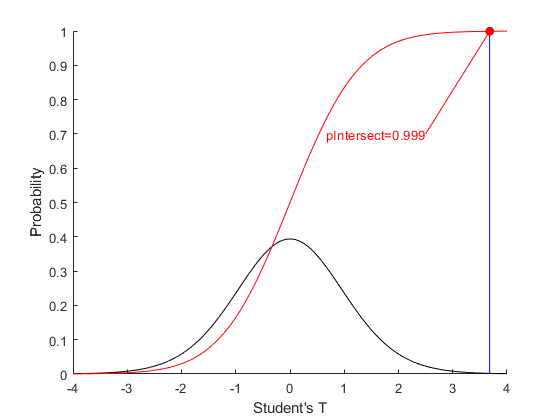

minT = -4;
maxT = 4;
dT = 0.05;
tBins= minT:dT:maxT;
figure(2);clf;hold on
dof = nrMeasurements -1;
plot(tBins,tpdf(tBins,dof),'k');
plot(tBins,tcdf(tBins,dof),'r');
plot([T T],get(gca,'YLim'),'b'); % The test statistic.
xlabel ('Student''s T');
ylabel ('Probability')

% Determine the cumulative probability at the test statistic T.
pIntersect  = tcdf(T,dof);
xStart = 2.5;
yStart = 0.7;
line([xStart T],[yStart pIntersect],'Color','red')
plot(T,pIntersect,'ro','MarkerFaceColor','red');
text(xStart,yStart,['pIntersect=' num2str(pIntersect,3)],'HorizontalAlignment','right',...
    'color','r')

pValueT = 1-pIntersect

pValueT = 7.9386e-04

Note that the horizontal axis is **not** the mean eye position, but a different test statistic calculated using Student's formula from the eye position sample. The interpretation of this figure, however, is very similar to the one above. 

The black curve shows that the test statistic T will most often be 0 under the null, but values of -1 or +1 are quite common too. The red curve shows that - under the null hypothesis - values less than -4 are very rare, that half of the values are less than 0 and that values above 4 are also rare. 

Finally the intersection of the cumulative null with the actual test statistic (blue line) is at p=0.999 which means that accorrding to the Student T-test, we can reject the null hypothesis with p<0.001. 

This use of the T-test followed the same logic as the simulated statistics for pedagogical reasons. (i.e to show that a statistical test involves comparing a test statistic to a cumuluative null distribution). This is not the recommended procecdure when you simply want to use the T-test. Matlab has a built in function for that and all the code above could be replaced with the following:

[H,p]= ttest(eyePosition,[],'tail',1)

H = 1

p = 7.9386e-04

Note that 'tail',1 means that we are testing for a mean that is larger than zero. We could also test whether the mean is less than zero (-1) or just different from zero (0). 

p contains the p-value of the statistical test. It matches the value calculated above. H is a logical that states whether the null hypothesis of zero mean can be rejected (H=1) or not (H=0). 

The shape of the Student T distribution depends on the number of measurements (i.e. the size of the sample). This makes sense because if you take more measurements, then your estimate of the T statistic gets better and better, hence a large value is increasingly unlikely to occur by chance. In other words by increasing the size of the sample, the T distribution becomes more narrow, and the cumulative distribution rises more rapidly:

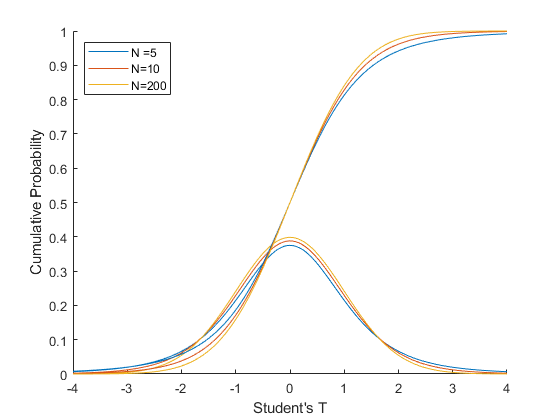

figure(3);clf;hold on;
plot(tBins,tpdf(tBins,5-1));
plot(tBins,tpdf(tBins,10-1));
plot(tBins,tpdf(tBins,200-1));
set(gca,'ColorOrderIndex',1);
plot(tBins,tcdf(tBins,5-1));
plot(tBins,tcdf(tBins,10-1));
plot(tBins,tcdf(tBins,200-1));
legend('N =5','N=10','N=200','location','northwest')
xlabel ('Student''s T');
ylabel ('Cumulative Probability')

The differences may look subtle, but they illustrate that a T value alone does not have much meaning, you can only interpret it if you also know the size of the sample and the corresponding *degrees of freedom* of the T-distribution. The *degrees of freedom* is the name of the parameter that determines the shape of the T-distribution (or you could say the parameter that is used to pick the appropriate T-distribution from a family of T-distributions). For a one-sample T-test, the degrees of freedom equals the size of the sample minus 1: `dof = nrMeasurements-1;`

Here is the logic of the (one-tailed) Student T-test:

- Make assumptions about the underlying data under the null hypothesis ($$\rightarrow $$ they are independently drawn from a normal distribution with a mean of zero)

- Calculate a test-statistic ($$\rightarrow $$ calculate `T`)

- Determine the cumulative null distribution of the test statistic ($$\rightarrow $$ use `tcdf`)

- Determine the probability of observing a value larger than `T` based on `tcdf`

- If the probabilty is less than some pre-specified significance level, reject the null hypothesis. 

Compare this with the steps of the Monte Carlo simulation:

- Make assumptions about the underlying data under the null hypothesis (drawn from a normal distrubition with mean of 0 and a standard deviation of 1)

- Extract a test-statistic (use `mean` to calculate `meanEyePosition`)

- Deteremine the cumuluative null distribution (`hist` & `cumsum`)

- Determine the probability of observing a mean larger than `meanEyeposition` based on the cumuluative null distribution

- If the probability is less than some significance lebel, reject the null hypothesis.

Step 1 in the Monte Carlo simulation is something I glossed over until now. When we generated simulated null data sets, I drew random numbers using `randn`. This means that all simulated samples were drawn from the normal distribution with mean 0 and standard deviation of 1. In other words the null hypothesis I simulated not only had a mean of zero but also a standard deviation of 1. In the specific example where I generated fake data using `randn` this was the correct thing to do: I knew that the data had a standard deviation of 1. But in a real experiment, you cannot know the true underlying standard deviation. We can, howewer, improve our Monte Carlo simulation by using the standard deviation of the sample in the simulations. The line

straightAhead = 0 + randn(nrMeasurements,nrRepeats);

becomes

sampleStdev = std(eyePosition);
straightAhead = 0 + sampleStdev*randn(nrMeasurements,nrRepeats);

This changes the null hypothesis to : "The samples are drawn from a normal distribution with a mean of zero and a standard deviation equal to the standard deviation of the sample". In general this is the best we can do: we don't really know what distribution the samples are drawn from. But given that we have few samples, our best bet is that the standard devaition of the distribution is the same as the standard deviation of the sample. Let's do a Monte Carlo test of this refined null hypothesis, following the same logic as above:

meanStraightAhead = mean(straightAhead);
count = histcounts(meanStraightAhead,eyePosEdges,'Normalization','count');
cumulative = cumsum(count)/nrRepeats;
ix  = find(eyePosBins>meanEyePosition,1,'first'); %First value beyond meanEyePosition
pIntersect = cumulative(ix);
pValueMonteCarloSampleStd = 1-pIntersect;

Now we can compare the p-values of the three methods. 

pValueMonteCarlo 

pValueMonteCarlo = 0.0088

pValueMonteCarloSampleStd

pValueMonteCarloSampleStd = 8.0000e-05

pValueT

pValueT = 7.9386e-04

They are different because the null hypothesis are (subtly) different, but the last two are more similar becuase they both effectively estimate the standard deviation of the underlying distribution from the sample. 

In addition, you should note that the Monte Carlo tests depend on the luck of the draw; the test statistic is compared to the null based on `nrRepeats` simulations, but this null depends on how Matlab generates its (pseudo) random numbers. The T-test does not simulate the null distribution but calculates it and returns the same numbers every time. 

## The T-Test and its assumptions

For simple tests, the Monte Carlo simulation approach shown here is not typically used. I show it here mainly to help you understand how the T-test works. Conceptualy the T-test is the same as the simulations, except that we already know the null distribution so we don't have to do the simulations. Simulated null distributions play a bigger role once we start testing for the signficance of quantities more complex than the mean, or if we do not wish to make the assumptions that underlie the T-test: the normality of the underlying data set.

## False Positives

There are two ways in which a statistical test can fail. A test can claim that there is an effect while there is really no effect; this is called a **false positive** or a type-I error. Or, the test can claim that there is no effect while there really is one; this is a **false negative**, or a type-II error. 

To make this more specific, let's consider the T-Test that we've been looking at so far. This test (with 'tail',1) determines whether the sample has a mean larger than zero. A false positive corresponds to the situtation where we provided a sample that actually comes from a normal distirbution with mean zero but the `ttest`() function reports that the sample is significantly larger than from zero.

Let's estimate how often false positives occur:

% First, draw eye positions from a normal distribution with mean zero:
eyePosition = randn(nrMeasurements,nrRepeats);
% Perform a T-test on each one of the repeats:
[H05] = ttest(eyePosition,[],'tail',1);
% Determine how often the t-test rejects the null hypothesis on average:
mean(H05)

ans = 0.0502

Because each of the samples was drawn from a normal distribution with mean zero, every time the t-test rejects the null hypothesis (H05==1) is a false positive. So, we have ~5% false positives or type-I errors. 

Any statistical test will have false positives, that is simply the nature of a statistical test. By convention, the risk of 5% false positives is considered acceptable. The 5% number is called the significance level and sometimes referred to as $$\alpha $$. If a statistical test with a false positive rate of 5% rejects the null hypothesis, we consider the finding "statistically significant at the 0.05 significance level". This is commonly written as: (p<0.05).

The 5% or p<0.05 significance level, however, is just a convention. You can impose a more stringent/conservative criterion level of significance. For instance, if you are testing a drug for effectiveness, you'd probably want to be more conservative before you start prescribing it to patients. With the `ttest` function you specify the false positive rate that you find acceptable. For instance, if you are only willing to accept results that are significant at the 0.01 level (i.e. $$\alpha = 0.01 $$, or 1% false positives), you write:

[H01] = ttest(eyePosition,[],'tail',1,'alpha',0.01);
mean(H01)

ans = 0.0098

The data are exactly the same as before, but now the null hypothesis is rejected (H01==1) for only 1% of the samples. Presumably these are the samples in which the mean was higher. Let's confirm that:

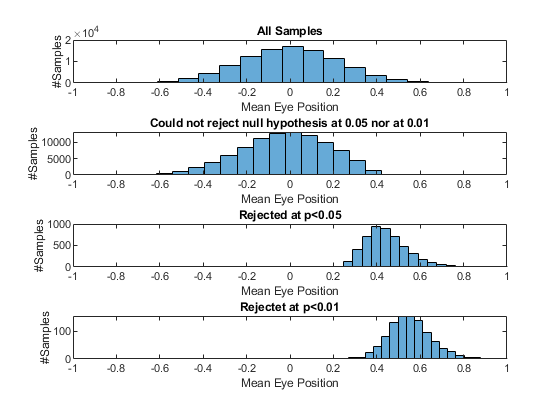

figure(4);
nrBins =20;
meanEyePosition = mean(eyePosition); % Mean per sample
subplot(4,1,1);
histogram(meanEyePosition,nrBins); % hist of all samples
set(gca,'XLim',[-1 1]);
xlabel 'Mean Eye Position'
ylabel '#Samples'
title 'All Samples'
subplot(4,1,2);
histogram(meanEyePosition(~(H05==1|H01==1)),nrBins); 
set(gca,'XLim',[-1 1]);
xlabel 'Mean Eye Position'
ylabel '#Samples'
title 'Could not reject null hypothesis at 0.05 nor at 0.01'
subplot(4,1,3);
histogram(meanEyePosition(H05==1),nrBins);
set(gca,'XLim',[-1 1]);
xlabel 'Mean Eye Position'
ylabel '#Samples'
title 'Rejected at p<0.05'
subplot(4,1,4);
histogram(meanEyePosition(H01==1),nrBins);
set(gca,'XLim',[-1 1]);
xlabel 'Mean Eye Position'
ylabel '#Samples'
title 'Rejectet at p<0.01'

The graph confirms the intuition that rejecting the null hypothesis at a significance level of 0.01 requires *on average* a mean that is higher.

Before we move on to false negatives, think about the data in this figure again; all samples (i.e. sets of `nrMeasurements` data points) were drawn from a normal distribution with a mean of zero. This means that you, the all-knowing generator of the data, know that the null hypothesis is corrrect (and should not be rejected). The T-test , however, does not have access to the way the noise in the data is generated; it assumes it came from a normal distribution and based on that limited knowledge decides whether the mean is unusually large or not.

## False Negatives & Power

Just as all statistical tests have false positives, they also have false negatives. For instance when the one-tailed T-test is provided a sample drawn from a normal distribution with a positive mean, but the test claims that the null hypothesis can **not** be rejected. (i.e. the test states that it is not unlikely that the sample could have been drawn from a normal distribution with a mean of zero.)

To investigate this, we generate samples from a random distribution with a known non-zero mean. 

meanEyePosition = 0.025:0.025:1; % Vary the mean from 0 to 1.
nrMeanEyePositions = numel(meanEyePosition);
% Generate eyePosition samples. For each meanEyePosition we simulate
% nrRepeats samples, and each sample has nrMeasurements measurements.
eyePosition = repmat(meanEyePosition,[nrMeasurements 1 nrRepeats]) + ...
                        randn(nrMeasurements,nrMeanEyePositions,nrRepeats);
[H,p] = ttest(eyePosition,[],'tail',1);

In these simulated data we **know** that each sample was drawn from a normal distribution with non-zero mean. In other words, we know that the null hypothesis should be corrected in each case. Turning this around, every time that the null hypothesis is not rejected (H==0), is a false negative.

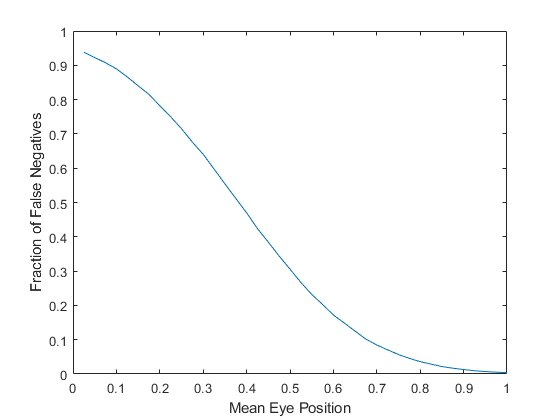

falseNegatives = mean(H==0,3); 
figure(5);
clf;
plot(meanEyePosition,falseNegatives);
xlabel 'Mean Eye Position'
ylabel('Fraction of False Negatives')

When the mean of the underlying distribution (mean eye position) is small, the T-test has many false negatives. This should not be surprising; if there is only a small effect ( a small mean) then it should be difficult to detect. With increasing effect size (in this case the mean eye position), the number of false negatives becomes progressively smaller. 

That is a general principle; the larger the effect (i.e. in this case the larger the mean of the underlying distribution), the smaller the fraction of false negatives. However, the rate at which the false negatives are reduced is something that is specific to each test. For some tests (such as the T-test) the false negatives drop off rapidly, for other tests you need larger effect sizes before your false negatives start to drop off.

A common way to quantify this property of a test is called the power of a statistical test, sometimes referred to as $$\beta $$. It corresponds to the probability of rejecting the null hypothesis if it is indeed incorrect. In other words, it corresponds to 1-P(false negatives). By convention a test with a power of 0.8 is considered good enough (i.e. 20% false negatives are considered acceptable). As you can see from the graph, the power depends on the effect size. In this example, the T-test reaches a power of 0.8 for a mean eye position (effect size) of 0.575. 

*The question whether false postives or false negatives are "worse" depends on context. In most scientific publications we try to limit false positives to less than 5% but are less stringent about false negatives (<20%). But if you think about the statistical test used in a nuclear reactor to determine whether the temperature is above some critical safety level, then it is clear that some false negatives can be disastrous (meltdown) while the consequences of false positives (waking up an engineer to check out the machine) are relatively harmless.*

## Assignments